% ESA Dynamics HW 3 - Planar Pendulum
% Chris Allum 4.15.21
clc
clearvars

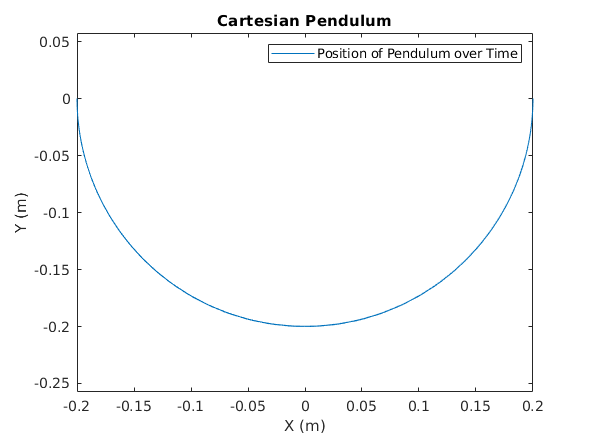

% initial position
r0 = .2;
theta0 = pi/2;

% initial velocity
dr0 = 0;
dtheta0 = 0;


% pack initial conditions into column vector
init = [r0 dr0 theta0 dtheta0]';

% run simulation cartesian
[t1,p1] = PendulumA(init);

% plot cartesian
x1 = p1(:,1);
y1 = p1(:,3);

figure
plot(x1,y1)
title("Cartesian Pendulum")
xlabel("X (m)")
ylabel("Y (m)")
legend(["Position of Pendulum over Time"])
axis equal

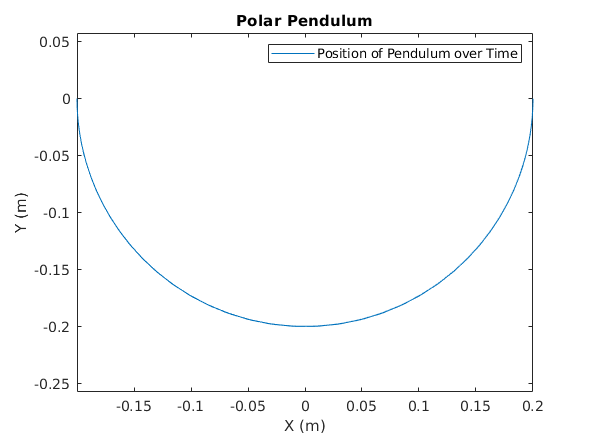


% run simulation polar
[t2,p2] = PendulumB(init);

% plot polar
x2 = p2(:,1).*sin(p2(:,3));
y2 = -p2(:,1).*cos(p2(:,3));

figure
plot(x2,y2)
title("Polar Pendulum")
xlabel("X (m)")
ylabel("Y (m)")
legend(["Position of Pendulum over Time"])
axis equal

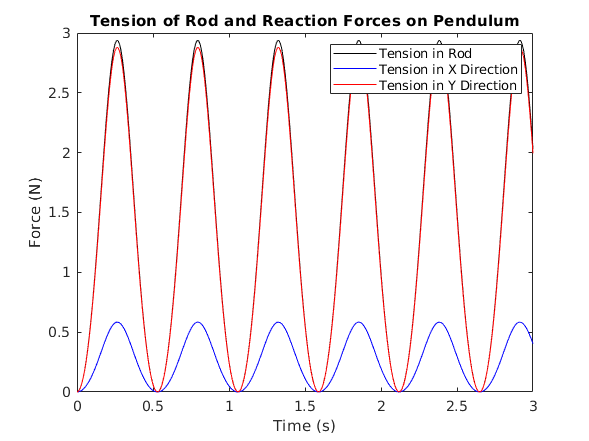


% plot reaction forces and tension
m = 0.1;
g = 9.8;
tension = m.*(g.*cos(p2(:,3)) + p2(:,1).*p2(:,4).^2);
tension_x = tension*sin(p2(3));
tension_y = tension*cos(p2(3));

figure
plot(t2,tension,"-k"), hold on
plot(t2,tension_x,"-b"),
plot(t2,tension_y,"-r")
title("Tension of Rod and Reaction Forces on Pendulum")
xlabel("Time (s)")
ylabel("Force (N)")
legend(["Tension in Rod","Tension in X Direction","Tension in Y Direction"])

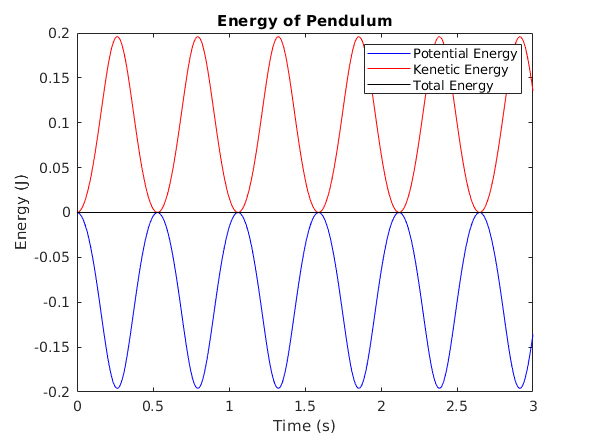


% energy calcs

figure
PE = m*g*y2;
KE = 0.5*m.*(p2(:,1).*p2(:,4)).^2;
plot(t2,PE,"-b"),hold on
plot(t2,KE,"-r")
plot(t2,PE+KE,"-k")
title("Energy of Pendulum")
xlabel("Time (s)")
ylabel("Energy (J)")
legend(["Potential Energy","Kenetic Energy","Total Energy"])

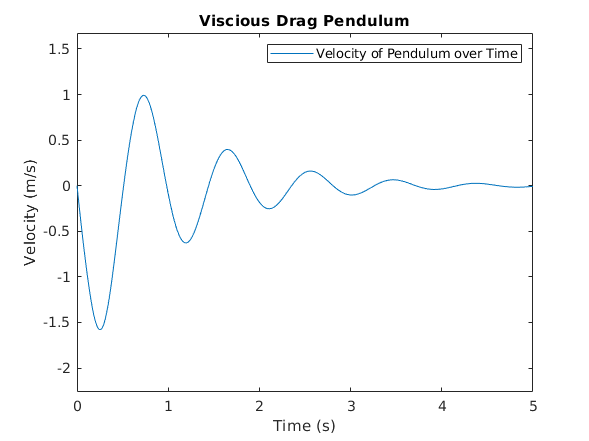


% run simulation viscous drag
[t3,p3] = PendulumC(init);

% plot viscous drag
viscous_speed = p3(:,1).*p3(:,4);

figure
plot(t3,viscous_speed)
title("Viscious Drag Pendulum")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend(["Velocity of Pendulum over Time"])
axis equal

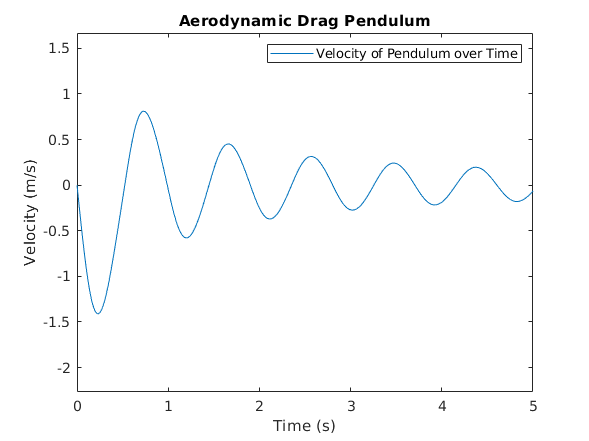


% run simulation aero drag
[t4,p4] = PendulumD(init);

% plot viscous drag
aero_speed = p4(:,1).*p4(:,4);

figure
plot(t4,aero_speed)
title("Aerodynamic Drag Pendulum")
xlabel("Time (s)")
ylabel("Velocity (m/s)")
legend(["Velocity of Pendulum over Time"])
axis equal

function [t,p] = PendulumA(init)
    
    % time span
    tspan = [0:.01:5];
    
    % simulation params, used in ODE funcs
    m = 0.1;
    l = 0.2;
    g = 9.8;
    
    % convert polar init to cartesian
    r = init(1);
    theta = init(3);
    x = r*sin(theta);
    dx = 0;
    y = -r*cos(theta);
    dy = 0;
    
    % recreate init condidtions in cartesian
    init = [x dx y dy]';
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        Q = [1 0 0 0 0;
             0 m 0 0 p(1)/l;
             0 0 1 0 0;
             0 0 0 m p(3)/l;
             0 p(1) 0 p(3) 0];
             
        R = [p(2) 0 p(4) -m*g -p(2)^2-p(4)^2]';
        
        z = (Q\R)';
        
        dx = z(1);
        ddx = z(2);
        dy = z(3);
        ddy = z(4);
        
        dpdt = [dx ddx dy ddy]';

    end

end


function [t,p] = PendulumB(init)
    
    % time span
    tspan = [0:.01:3];
    
    % simulation params, used in ODE funcs
    m = 0.1;
    l = 0.2;
    g = 9.8;
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        dr = p(2);  % r velocity
        ddr = 0;    % r accel
        dtheta = p(4);  % theta velocity
        ddtheta = -g/l*sin(p(3));    % theta accel
        
        % pack ODEs into column vector
        dpdt = [dr ddr dtheta ddtheta]';
    end

end

function [t,p] = PendulumC(init)
    
    % time span
    tspan = [0:.01:5];
    
    % simulation params, used in ODE funcs
    m = 0.1;
    l = 0.2;
    g = 9.8;
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        dr = p(2);  % r velocity
        ddr = 0;    % r accel
        dtheta = p(4);  % theta velocity
        ddtheta = -g/l*sin(p(3)) - 2*p(4);    % theta accel
        
        % pack ODEs into column vector
        dpdt = [dr ddr dtheta ddtheta]';
    end

end

function [t,p] = PendulumD(init)
    
    % time span
    tspan = [0:.01:5];
    
    % simulation params, used in ODE funcs
    m = 0.1;
    l = 0.2;
    g = 9.8;
    
    % use ode45 and stop at event
    options = odeset("RelTol",1.0e-6);
    [t,p] = ode45(@f,tspan,init,options);
    
    % define ODEs
    function dpdt = f(~,p)
        dr = p(2);  % r velocity
        ddr = 0;    % r accel
        dtheta = p(4);  % theta velocity
        ddtheta = -g/l*sin(p(3)) - .5.*(-1)^(p(4)<0).*p(4)^2;    % theta accel
        
        % pack ODEs into column vector
        dpdt = [dr ddr dtheta ddtheta]';
    end

end